The goal of this code is to investigate the effects of the initial coniditon on the convergence of the DDM algorithm. Specifically, we are interested in 2 questions

Q1) Are there any initializations for which the DDM algorithm doesn't converge (this may depend on the solution itself)?

Q2) How does each inititalization effect the convergence rate for the DDM solution

We begin by solving on a coarse mesh for the smooth example solution 

addpath('Subroutines')
clear

% Parameters needed to generate grid
x0 = -1; x1 = 1;
y0 = -1; y1 = 1;
N = 2^4+1;
h = (x1-x0)/(N+1);
depth = ceil(h^(-1/3));
% choose F
choice = 1;
switch(choice)
   case 1
      DirBC = @(x,y) (exp((x.^2+y.^2)/2));
      contF = @(x,y) ((1+x.^2+y.^2).*exp(x.^2+y.^2));
   case 2
      pos = @(x) max(x,0);
      DirBC = @(x,y) (.5*pos(((x-.5).^2+(y-.5).^2).^.5-.2).^2);
      contF = @(x,y) (pos(1-.2./sqrt((x-.5).^2+(y-.5).^2)));
   case 3
      DirBC = @(x,y) (-sqrt(2-(x.^2+y.^2)));
      contF = @(x,y) (2*(2-(x.^2+y.^2)).^-2);
end
% Call mesh builder
[pCoarse,Interior,Boundary,NMatSDD,CMatSDD,theta] = buildMesh_Rect(x0,x1,y0,y1,h,depth);

% solver settings
order = 2;
epsilon = (h*depth)^2;
weight = quadWeights(theta,order);


% discrete operator on the whole space
vCount = length(theta);
aproxMAOp = @(u)(pi^2*((SDDMat(NMatSDD,CMatSDD,u,vCount,epsilon).^(-1))*weight).^(-2)+min(min(SDDMat(NMatSDD,CMatSDD,u,vCount,-Inf),epsilon),[],2));

% Precompute Dvv matrices
Dvvs = cell(length(theta),1);
for i = 1:length(theta)
   Dvvs{i} = sparse( repmat(Interior,1,3), [NMatSDD(:,i*3-2) NMatSDD(:,i*3-1) NMatSDD(:,i*3)], [CMatSDD(:,i*3-2) CMatSDD(:,i*3-1) CMatSDD(:,i*3)], length(Interior), length(pCoarse));
end 

% exact solutions
exact = DirBC(pCoarse(Interior,1),pCoarse(Interior,2));

% solve without doing DDM
F = contF(pCoarse(Interior,1),pCoarse(Interior,2));
uBdry = DirBC(pCoarse(Boundary,1),pCoarse(Boundary,2));


The standard way on initializing the Newton's method is to use the first step of a low order iterative scheme which solves a related poisson equation. As long as the newton's method converges, for our purposes it shouldn't matter what the initialization for this solution is

uInit = poissonInit(NMatSDD,CMatSDD,F,uBdry,1,(vCount+1)/2);
uCoarse = quadSolver2(NMatSDD,CMatSDD,Dvvs,F,uBdry,epsilon,weight,h,Inf,uInit);

We measure the error her in the sup norm

min_err = norm(exact-uCoarse(Interior),inf)

min_err = 0.0390

How does this coarse solution and it's intitialization compare to the true solution?

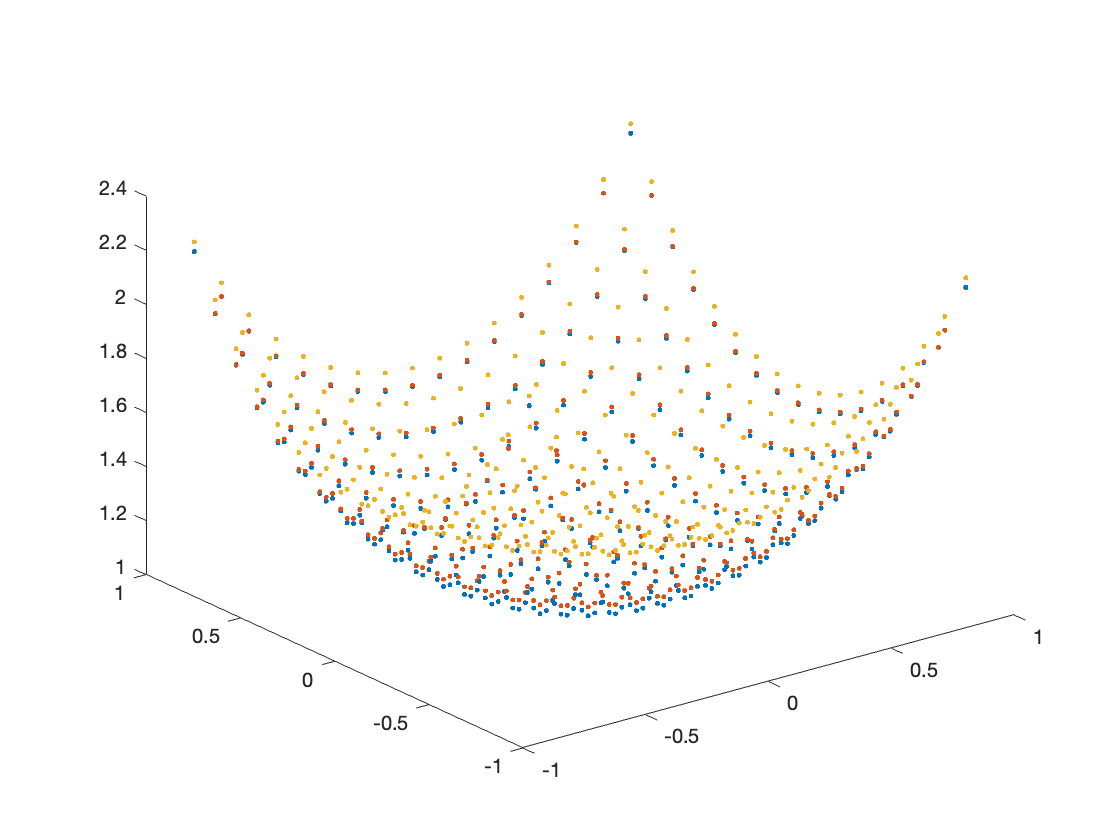

figure, title('Grid Functions')
plot3(pCoarse(Interior,1),pCoarse(Interior,2),exact,'.')
hold on
plot3(pCoarse(Interior,1),pCoarse(Interior,2),uCoarse(Interior),'.')
plot3(pCoarse(Interior,1),pCoarse(Interior,2),uInit,'.')

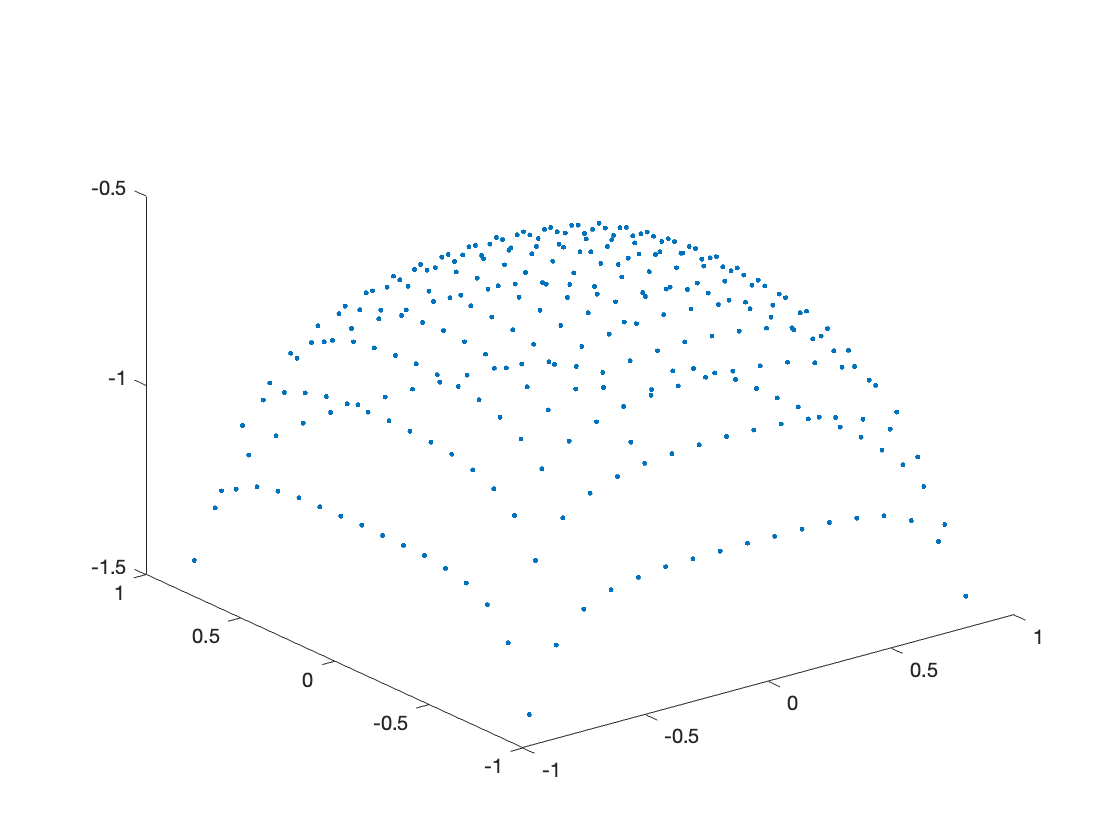


figure, title('uInit error')
plot3(pCoarse(Interior,1),pCoarse(Interior,2),log10(abs(exact-uInit)),'.')

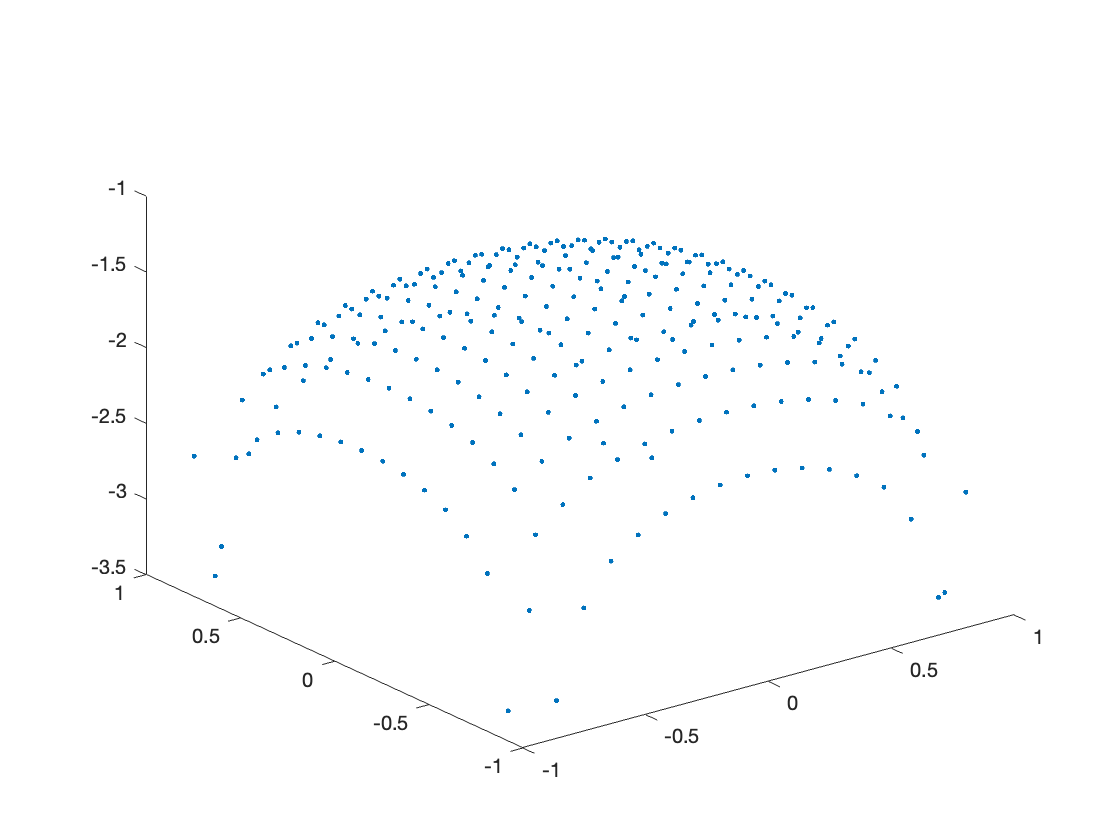


figure, title('uCoarse error')
plot3(pCoarse(Interior,1),pCoarse(Interior,2),log10(abs(exact-uCoarse(Interior))),'.')

While the uInit appers to be relativelty close in terms of the error, we see qualitativelty from the graphs of the solution that it's error is on the scale of the solution and not of the grid resolution. That is, the yellow graph is very far from the blue and red ones. We can also view how well do these different grid functions fit into the discrete operator.

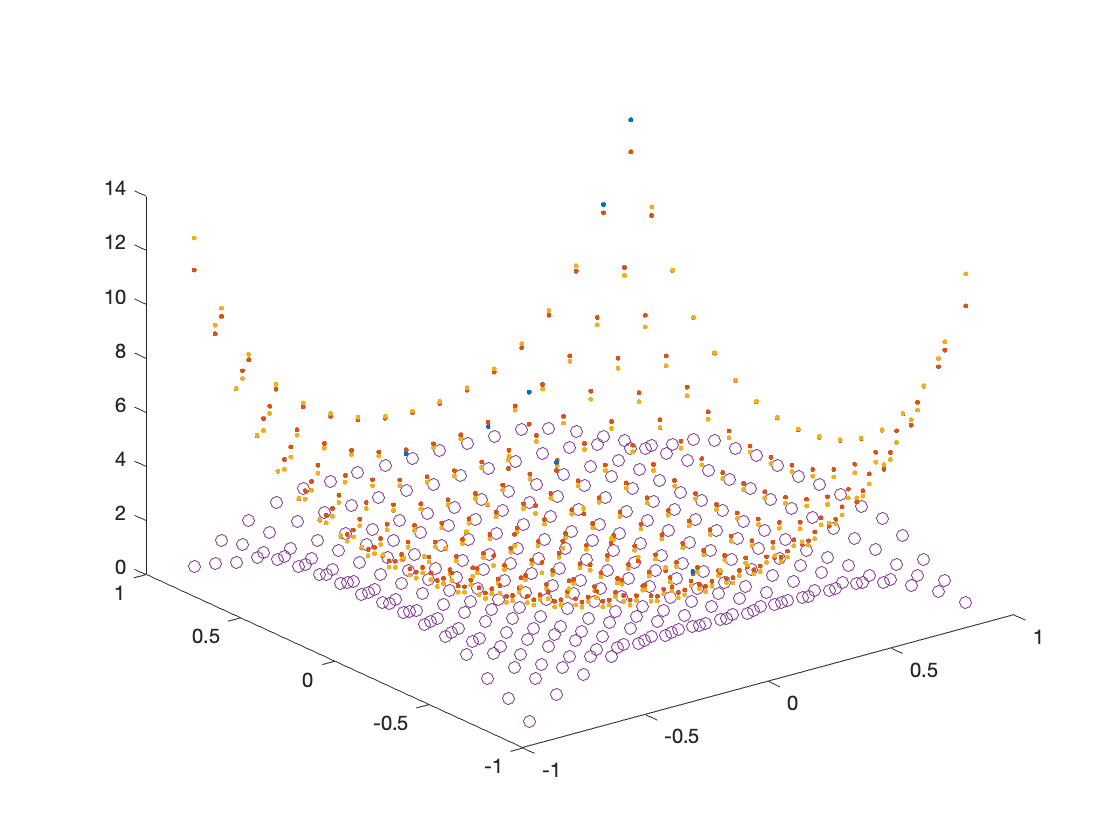

figure, title('Approximate Source')
plot3(pCoarse(Interior,1),pCoarse(Interior,2),F,'.')
hold on
plot3(pCoarse(Interior,1),pCoarse(Interior,2),aproxMAOp([exact;uBdry]),'.')
plot3(pCoarse(Interior,1),pCoarse(Interior,2),aproxMAOp(uCoarse),'.')
plot3(pCoarse(Interior,1),pCoarse(Interior,2),aproxMAOp([uInit;uBdry]),'o')

We can see right away that both the exact and coarse solutions fit the source data fairly well while the uInit is completely different. This also demonstrates a key challenge with solving a nonlinear problem. Even though the uInit is relatively close to the solution, it does not map to a nearby source. 

We are no interested with solving the problem on a more refined grid. 

N = 2^7+1;
h = (x1-x0)/(N+1);
depth = ceil(h^(-1/3));
[Points,Interior,Boundary,NMatSDD,CMatSDD,theta] = buildMesh_Rect(x0,x1,y0,y1,h,depth);
epsilon = (h*depth)^2;
weight = quadWeights(theta,order);

vCount = length(theta);
aproxMAOp = @(u)(pi^2*((SDDMat(NMatSDD,CMatSDD,u,vCount,epsilon).^(-1))*weight).^(-2)+min(min(SDDMat(NMatSDD,CMatSDD,u,vCount,-Inf),epsilon),[],2));

% Precompute Dvv matrices
Dvvs = cell(length(theta),1);
for i = 1:length(theta)
    Dvvs{i} = sparse( repmat(Interior,1,3), [NMatSDD(:,i*3-2) NMatSDD(:,i*3-1) NMatSDD(:,i*3)], [CMatSDD(:,i*3-2) CMatSDD(:,i*3-1) CMatSDD(:,i*3)], length(Interior), length(Points));
end 

% exact solutions
exact = DirBC(Points(Interior,1),Points(Interior,2));

% solve without doing DDM
F = contF(Points(Interior,1),Points(Interior,2));
uBdry = DirBC(Points(Boundary,1),Points(Boundary,2));


We'll inititalize the solution method by interpolating the coarse solution onto the the more refined grid, and compare the results with initializing with different methods

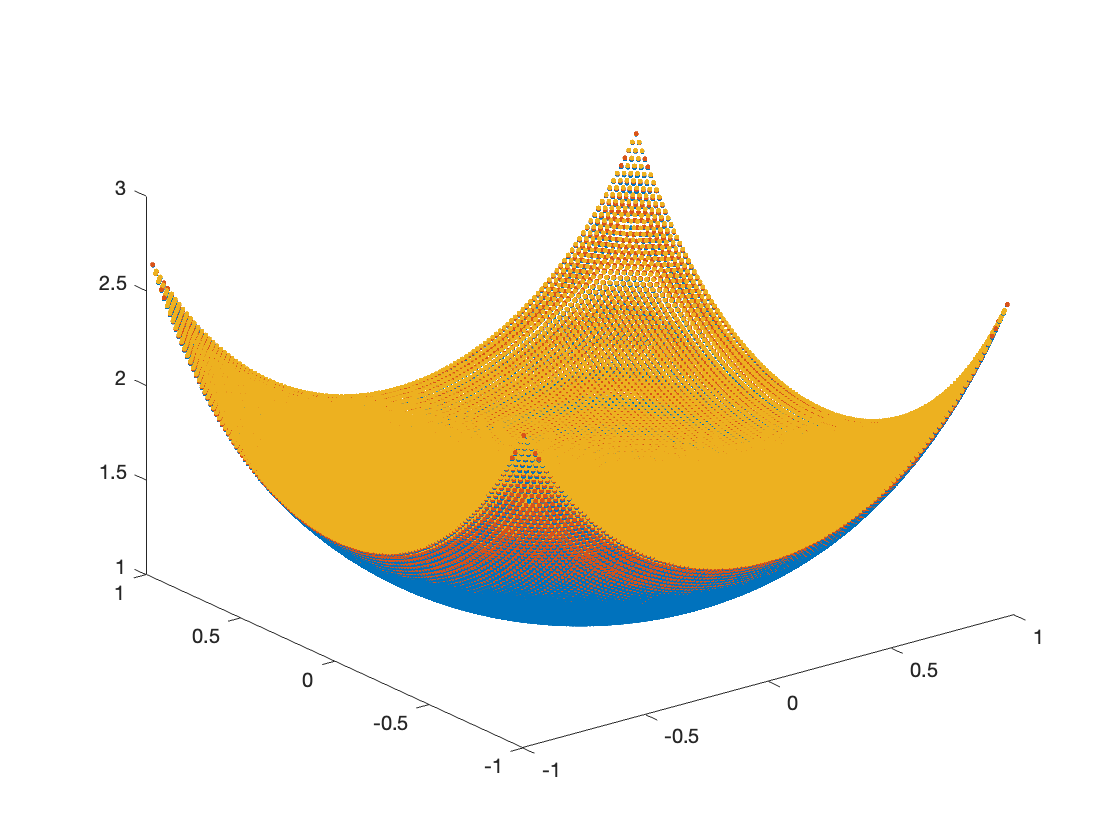


uInterp = griddata(pCoarse(:,1),pCoarse(:,2),full(uCoarse),Points(Interior,1),Points(Interior,2));
uPM = poissonInit(NMatSDD,CMatSDD,F,uBdry,1,(vCount+1)/2);
uZ = zeros(size(F));


figure, title('Refined Grid Functions')
plot3(Points(Interior,1),Points(Interior,2),exact,'.')
hold on
plot3(Points(Interior,1),Points(Interior,2),uInterp,'.')
plot3(Points(Interior,1),Points(Interior,2),uPM,'.')

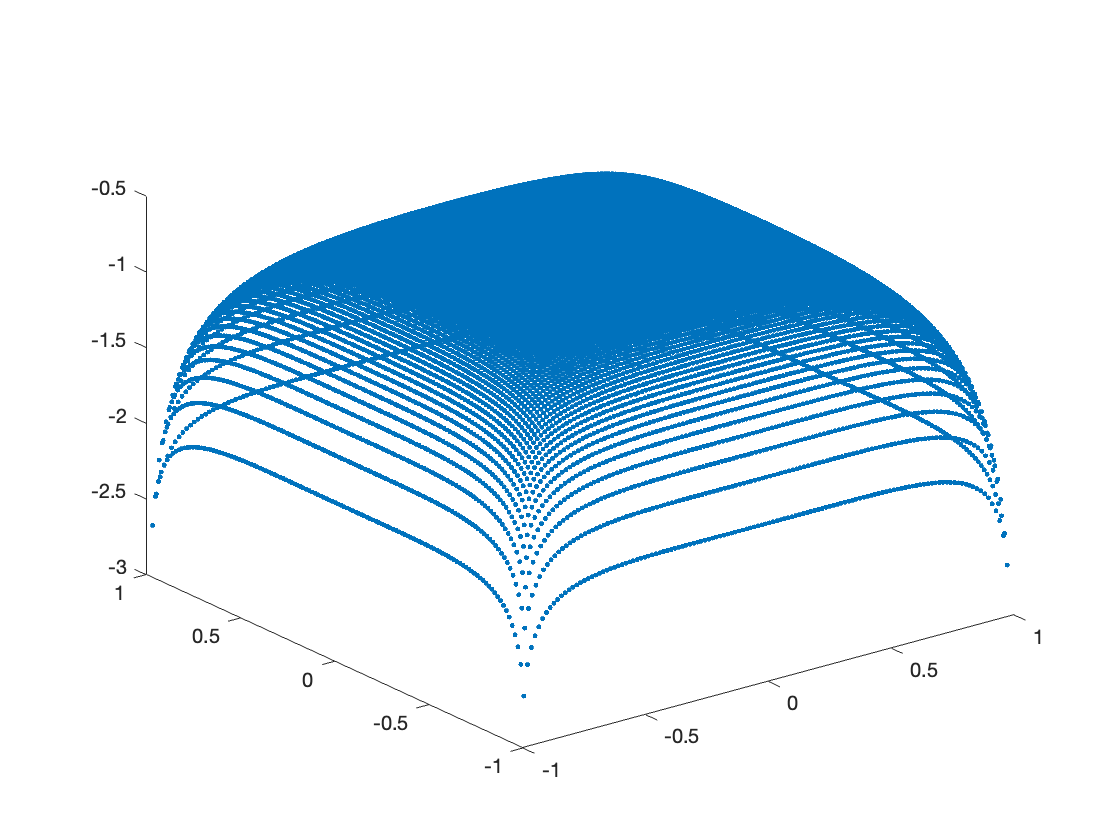



figure, title('uInit error')
plot3(Points(Interior,1),Points(Interior,2),log10(abs(exact-uPM)),'.')

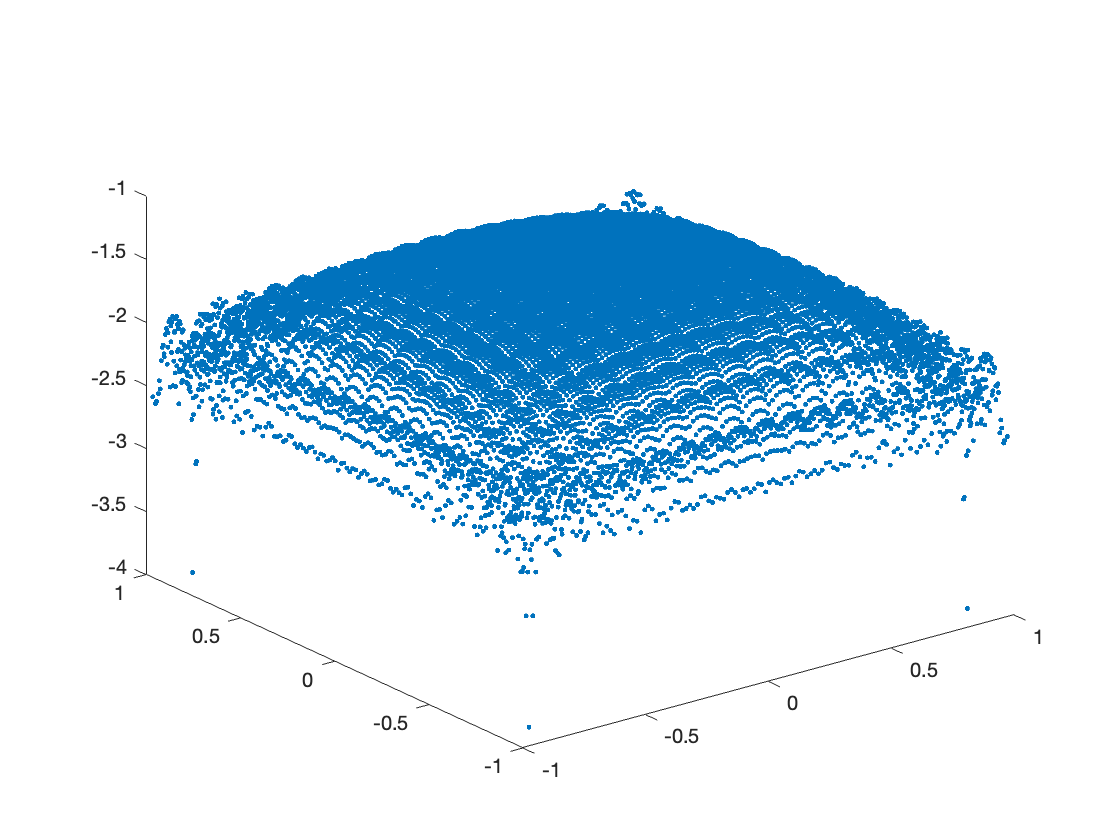


figure, title('uCoarse error')
plot3(Points(Interior,1),Points(Interior,2),log10(abs(exact-uInterp)),'.')

Again, we can see that the error is only slightly better for the Interp than uInit, however there is a qualitivative difference between the two solutions

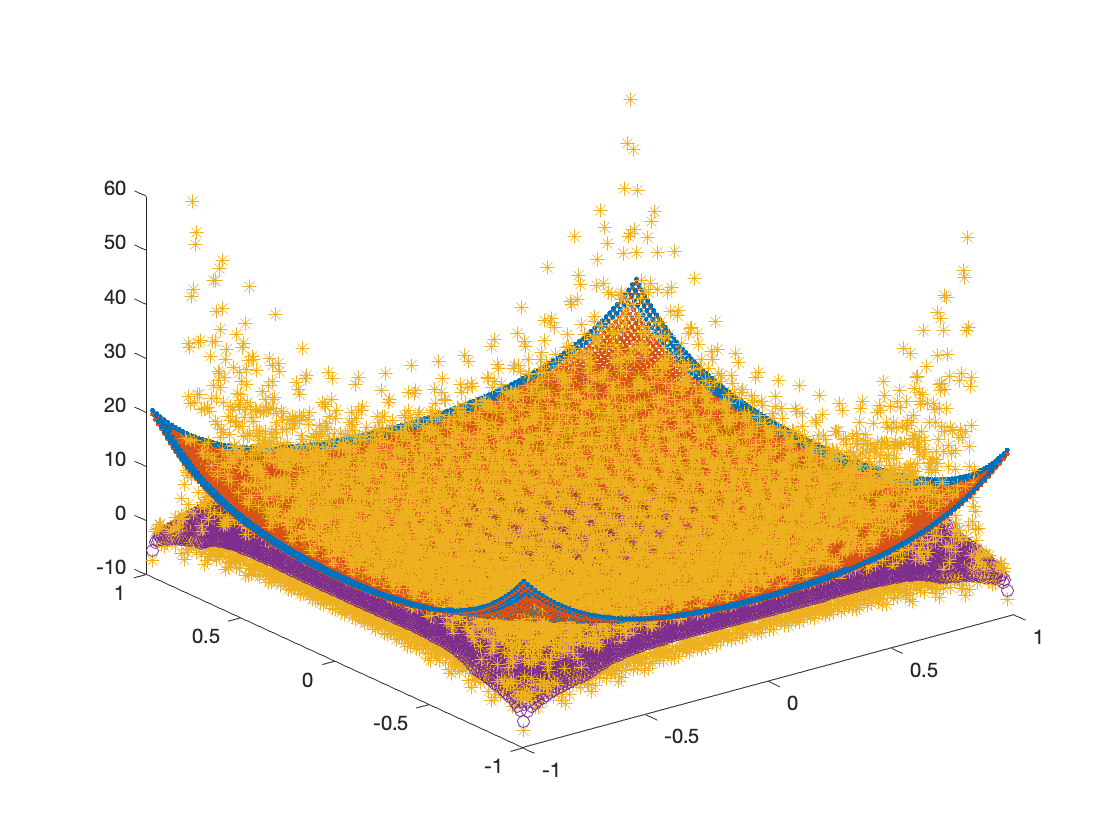

figure, title('Approximate Source')
plot3(Points(Interior,1),Points(Interior,2),F,'.')
hold on
plot3(Points(Interior,1),Points(Interior,2),aproxMAOp([exact;uBdry]),'.')
plot3(Points(Interior,1),Points(Interior,2),aproxMAOp([uInterp;uBdry]),'*')
plot3(Points(Interior,1),Points(Interior,2),aproxMAOp([uPM;uBdry]),'o')

Clearly the uInterp isn't as close to the source as the exact solution is, and the eventual computation will also be closer, but it has some qualitative similarities to the actual source which will make it a better initial guess than uPM. We demonstate this now by considering 3 different methods for initializing Newton's Method


[uNewt,t,stepcount] = quadSolver2(NMatSDD,CMatSDD,Dvvs,F,uBdry,epsilon,weight,h,Inf,uInterp);
Interp_time = t

Interp_time = 3.2745

Interp_count = stepcount

Interp_count = 6

Interp_error = norm(exact-uNewt(Interior),inf)

Interp_error = 0.0022


[uNewt,t,stepcount] = quadSolver2(NMatSDD,CMatSDD,Dvvs,F,uBdry,epsilon,weight,h,Inf,uPM);
PM_time = t

PM_time = 7.2345

PM_count = stepcount

PM_count = 8

PM_error = norm(exact-uNewt(Interior),inf)

PM_error = 0.0022



[uNewt,t,stepcount] = quadSolver2(NMatSDD,CMatSDD,Dvvs,F,uBdry,epsilon,weight,h,Inf,uZ);

Z_time = t

Z_time = 12.0585

Z_count = stepcount

Z_count = 21

Z_error = norm(exact-uNewt(Interior),inf)

Z_error = 0.0022

All three inititalization methods lead to a solution with the same error, however they all took different amounts of time and newton steps to converge. It's worth noting that the average time per newton's step also varied for each of the three methods. Understanding why this happens would require a deeper dive into the newton's method itself. This may no always be the case, we cannot at this point guarantee that an interpolation from a coarse solution will provide a good initialization for newton's method. However, we also cannot guarantee that the solution of the poisson equation will be a good initializaiton either. 

Is there a similar effect on the initialization for the domain decomposition methods?


overlap = ceil((N-1)/5);
% DDM settings
max_iter = 200;
conv_iter = max_iter;
% tol = 1e-6;
tol = h;
delta = h*overlap;

uDDM = [uInterp;uBdry];
[subInd,subOL] = fourSquares(x0,x1,y0,y1,delta,Points,Interior);
Doms = subDoms(NMatSDD,CMatSDD,Dvvs,subInd,subOL,F,uDDM);

ress = zeros(max_iter,1);
err_direct = zeros(max_iter,1);
err_exact = zeros(max_iter,1);
newt_iters = zeros(max_iter,1);

ddmtime = tic;
output = cell(1,4);

% Run the ddm iterations
for k = 1:max_iter
    M = 1;
    % Run each local solver
    [out1,newt1] = dom2qs(Doms(1),epsilon,weight,h,M); % call solver
    [out2,newt2] = dom2qs(Doms(2),epsilon,weight,h,M); % call solver
    [out3,newt3] = dom2qs(Doms(3),epsilon,weight,h,M);
    [out4,newt4] = dom2qs(Doms(4),epsilon,weight,h,M);
    newt_iters(k) = newt1+newt2+newt3+newt4;
    
    % Recombine without any relaxation or averaging, just taking the
    % subsolutions on disjoint squares
    % Can modify for more flexibility
    [Doms,uDDM] = updater(out1,out2,out3,out4,Doms,uDDM);

    % Using the nonlinear residual instead of the residue, not sure what
    % the residue should be. 
    res = norm(aproxMAOp(uDDM)-F,Inf);

    %    % compute error from exact solution
       err_exact(k) = norm(uDDM(Interior)-exact,inf);
    %
    %    % compute discrepancy from direct numerical solver
       err_direct(k) = norm(uDDM(Interior)-uNewt(Interior),inf);
    %
       ress(k) = res;
    if (res < tol)
        conv_iter = k;
        break
    end
end
toc(ddmtime)

Elapsed time is 8.627816 seconds.


conv_iter

conv_iter = 11

err_direct(conv_iter)

ans = 8.9069e-06

uDDM = [uZ;uBdry];
[subInd,subOL] = fourSquares(x0,x1,y0,y1,delta,Points,Interior);
Doms = subDoms(NMatSDD,CMatSDD,Dvvs,subInd,subOL,F,uDDM);

ress = zeros(max_iter,1);
err_direct = zeros(max_iter,1);
err_exact = zeros(max_iter,1);
newt_iters = zeros(max_iter,1);

ddmtime = tic;
output = cell(1,4);

% Run the ddm iterations
for k = 1:max_iter
    M = 1;
    % Run each local solver
    [out1,newt1] = dom2qs(Doms(1),epsilon,weight,h,M); % call solver
    [out2,newt2] = dom2qs(Doms(2),epsilon,weight,h,M); % call solver
    [out3,newt3] = dom2qs(Doms(3),epsilon,weight,h,M);
    [out4,newt4] = dom2qs(Doms(4),epsilon,weight,h,M);
    newt_iters(k) = newt1+newt2+newt3+newt4;
    
    % Recombine without any relaxation or averaging, just taking the
    % subsolutions on disjoint squares
    % Can modify for more flexibility
    [Doms,uDDM] = updater(out1,out2,out3,out4,Doms,uDDM);

    % Using the nonlinear residual instead of the residue, not sure what
    % the residue should be. 
    res = norm(aproxMAOp(uDDM)-F,Inf);

    %    % compute error from exact solution
       err_exact(k) = norm(uDDM(Interior)-exact,inf);
    %
    %    % compute discrepancy from direct numerical solver
       err_direct(k) = norm(uDDM(Interior)-uNewt(Interior),inf);
    %
       ress(k) = res;
    if (res < tol)
        conv_iter = k;
        break
    end
end

toc(ddmtime)

Elapsed time is 20.670249 seconds.


conv_iter

conv_iter = 27

err_direct(conv_iter)

ans = 1.0034e-04


uDDM = [uPM;uBdry];
[subInd,subOL] = fourSquares(x0,x1,y0,y1,delta,Points,Interior);
Doms = subDoms(NMatSDD,CMatSDD,Dvvs,subInd,subOL,F,uDDM);

ress = zeros(max_iter,1);
err_direct = zeros(max_iter,1);
err_exact = zeros(max_iter,1);
newt_iters = zeros(max_iter,1);

ddmtime = tic;
output = cell(1,4);

% Run the ddm iterations
for k = 1:max_iter
    M = 1;
    % Run each local solver
    [out1,newt1] = dom2qs(Doms(1),epsilon,weight,h,M); % call solver
    [out2,newt2] = dom2qs(Doms(2),epsilon,weight,h,M); % call solver
    [out3,newt3] = dom2qs(Doms(3),epsilon,weight,h,M);
    [out4,newt4] = dom2qs(Doms(4),epsilon,weight,h,M);
    newt_iters(k) = newt1+newt2+newt3+newt4;
    
    % Recombine without any relaxation or averaging, just taking the
    % subsolutions on disjoint squares
    % Can modify for more flexibility
    [Doms,uDDM] = updater(out1,out2,out3,out4,Doms,uDDM);

    % Using the nonlinear residual instead of the residue, not sure what
    % the residue should be. 
    res = norm(aproxMAOp(uDDM)-F,Inf);

    %    % compute error from exact solution
       err_exact(k) = norm(uDDM(Interior)-exact,inf);
    %
    %    % compute discrepancy from direct numerical solver
       err_direct(k) = norm(uDDM(Interior)-uNewt(Interior),inf);
    %
       ress(k) = res;
    if (res < tol)
        conv_iter = k;
        break
    end
end
toc(ddmtime)

Elapsed time is 24.727259 seconds.


conv_iter

conv_iter = 14

err_direct(conv_iter)

ans = 1.0152e-04

In this DDM implemenation, we are only doing a single newton step per DDM step. It may be the case that doing the full newton steps will depend differently on the intitialization, but this seems unlikely. It is certainly clear that the interpolated values converged much faster, though again the average time per step wasn't what would be expected. The last thing we'll examine is the difference between full newton and single step newton with the interpolated valuyes 

uDDM = [uInterp;uBdry];
[subInd,subOL] = fourSquares(x0,x1,y0,y1,delta,Points,Interior);
Doms = subDoms(NMatSDD,CMatSDD,Dvvs,subInd,subOL,F,uDDM);

ress = zeros(max_iter,1);
err_direct = zeros(max_iter,1);
err_exact = zeros(max_iter,1);
newt_iters = zeros(max_iter,1);

ddmtime = tic;
output = cell(1,4);

% Run the ddm iterations
for k = 1:max_iter
    M = Inf;
    % Run each local solver
    [out1,newt1] = dom2qs(Doms(1),epsilon,weight,h,M); % call solver
    [out2,newt2] = dom2qs(Doms(2),epsilon,weight,h,M); % call solver
    [out3,newt3] = dom2qs(Doms(3),epsilon,weight,h,M);
    [out4,newt4] = dom2qs(Doms(4),epsilon,weight,h,M);
    newt_iters(k) = newt1+newt2+newt3+newt4;
    
    % Recombine without any relaxation or averaging, just taking the
    % subsolutions on disjoint squares
    % Can modify for more flexibility
    [Doms,uDDM] = updater(out1,out2,out3,out4,Doms,uDDM);

    % Using the nonlinear residual instead of the residue, not sure what
    % the residue should be. 
    res = norm(aproxMAOp(uDDM)-F,Inf);

    %    % compute error from exact solution
       err_exact(k) = norm(uDDM(Interior)-exact,inf);
    %
    %    % compute discrepancy from direct numerical solver
       err_direct(k) = norm(uDDM(Interior)-uNewt(Interior),inf);
    %
       ress(k) = res;
    if (res < tol)
        conv_iter = k;
        break
    end
end
toc(ddmtime)

Elapsed time is 9.893414 seconds.


conv_iter

conv_iter = 6

err_direct(conv_iter)

ans = 1.5142e-04

For this example, the single step newton's did seem to perform the best

function[output,newt] = dom2qs(Dom,epsilon,weight,h,M)

[output,~,newt] = quadSolver2(Dom.NMat_l,Dom.CMat_l,Dom.Dvvs_l,Dom.F_l,Dom.uBdry_l,epsilon,weight,h,M,Dom.uInt_l);

end

% Updates the global solution and the subsolutions
function[Doms,uDDM] = updater(out1,out2,out3,out4,Doms,uDDM)
    uDDM(Doms(1).nOL_g) = out1(Doms(1).nOL_l);
    uDDM(Doms(2).nOL_g) = out2(Doms(2).nOL_l);
    uDDM(Doms(3).nOL_g) = out3(Doms(3).nOL_l);
    uDDM(Doms(4).nOL_g) = out4(Doms(4).nOL_l);
    for kk = 1:4
        Doms(kk).uInt_l = uDDM(Doms(kk).I_g);
        Doms(kk).uBdry_l = uDDM(Doms(kk).B_g);
    end
end
